# Parameter estimation and identifiability, uncertainty, and sensitivity analyses for a COVID-19 model

**Implemented model**


$$\dot{S} = -\alpha\,S - \frac{\beta\,I\,S}{N} - \frac{\sigma\,S\,A}{N} - \eta\,S\\
\dot{A} =  -\tau\,A + \epsilon\,E\\
\dot{C} = \alpha\,S - \mu\,C\\
\dot{E} = -\gamma\,E + \frac{\beta\,I\,S}{N} + \mu\,C + \eta\,S + \frac{\sigma\,S\,A}{N} - \epsilon\,E\\
\dot{I} = \tau\,A + \gamma\,E - \delta\,I\\
\dot{R} = \lambda\,Q\\
\dot{Q} = \delta\,I - \lambda\,Q - k\,Q\\
\dot{D} = k\,Q\\$$


with $N = S + C + E + A + I + Q + R + D$ 

**Taken from **

Devosmita Sen and Debasis Sen. 2021. Use of a Modified SIRD Model to Analyze COVID-19 Data. Industrial & Engineering Chemistry Research 60 (11), 4251-4260. DOI: 10.1021/acs.iecr.0c04754

**Real data**

We implemented the number of COVID-19 cases per week reported for Amazonas, a department in Colombia, during the outbreak that occurred in 2020.

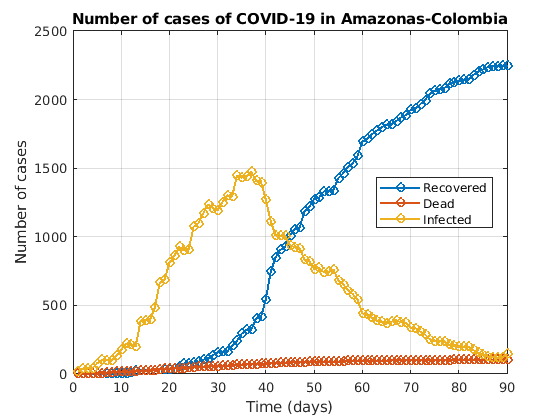

load('Amazonas.mat');

ydata = ydata(:, 10:end)';
ydata = [ydata(:,3), ydata(:,2), ydata(:,1)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

clf
plot(ydata, '-o', 'LineWidth',1.5)
xlim([0 90])
title('Number of cases of COVID-19 in Amazonas-Colombia')
ylabel('Number of cases')
xlabel('Time (days)')
grid on
legend({'Recovered','Dead','Infected'},"Location","best")

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(1,2) ydata(1,2);  %D    
            ydata(1,3) ydata(1,3);  %I
            7600 80000;      %S
            0 2000;               %A
            0 1000;              %C
            0 2000;               %E
            0 2000              %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1, 3];
% outs = [3];
[T,~] = gsua_dpmat(odes,vars,[0 length(xdata)],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \sigma & \tau \end{array}\right)$$

T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

**Parameter estimation**

First, define the optimization process options: *Solver, maximum function evaluation, maximum iterations per estimation*, among others.

Solver = 'fmincon';    
Opt = optimoptions('fmincon','UseParallel', false,'MaxFunctionEvaluations',30000, ...
    'MaxIterations', 3000, 'Display','off');

Define the number of parameter estimations to perform and define the vectors to save the estimated parameters and their respective cost value, i.e., residual.

N = 1000;
Residual = zeros(N,1);
Params = zeros(N,16);

parfor i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata(:,[1,3])','solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estfmincon;
end

Sort each set of parameters according to each residual value

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

save("Results/Estimations/Estimations_AmazonasComplex1.mat", "EstimatedParams", "ResidualSorted")

**Simulate some factor estimations**

We selected 1000-factor estimations to simulate. Those curves follow the trend of real data.

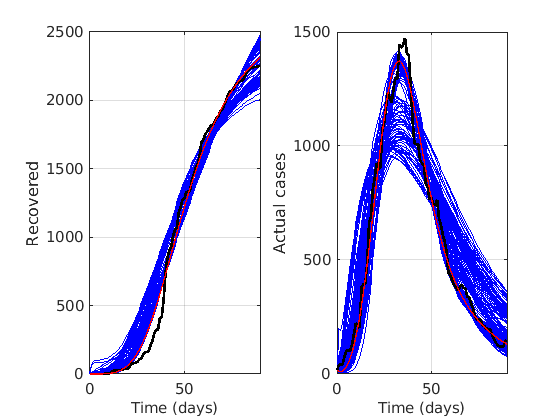

load("Results/Estimations/Estimations_Amazonas.mat");
load("Results/Estimations/Deepest_Amazonas.mat")

N = 1000;
ysim = zeros(N, 2, length(xdata));

parfor i = 1 : N
    ysim(i,:,:) = gsua_deval(EstimatedParams(i,:), T, xdata);
end
ydeep =  gsua_deval(Deep', T, xdata);

Labels = ["Recovered", "Actual cases"];
close all
figure
N2 = 800;
for j = 1:2
    subplot(1,2,j)
    plot(xdata, squeeze(ysim(1:N2,j,:)), 'b')
    hold on
    plot(xdata, ydata(:,outs(j)), 'k','Linewidth', 2)
    plot(xdata, ydeep(j,:), 'r','Linewidth', 1)
    xlim([0 90])
    grid on 
    ylabel(Labels(j))
    set(gca,'FontSize',11)
xlabel('Time (days)', 'FontSize', 11)    
end

**Best factor estimation curve**

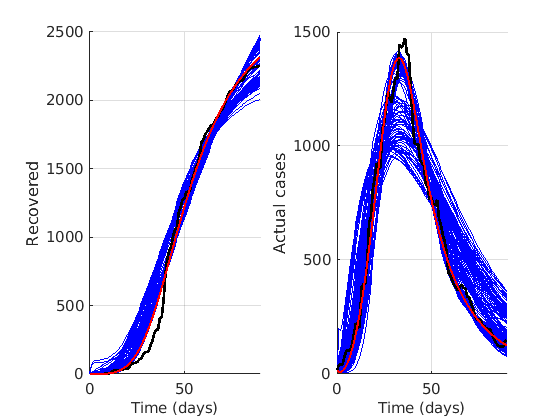

Best = squeeze(ysim(1,:,:));
BestParams = EstimatedParams(1,:);
% save("Results/Estimations/Best_Amazonas.mat", "BestParams","Best")
load("Results/Estimations/Deepest_Amazonas.mat")
close all
for j=1:2
    subplot(1,2,j)
    hold on
    plot(xdata, squeeze(ysim(1:N2,j,:)), 'b')
    plot(xdata, ydata(:,outs(j)), 'k','Linewidth', 2)
    plot(xdata, Best(j,:), 'r','Linewidth', 1.5)    
    ylabel(Labels(j))
    grid on
    set(gca,'FontSize',11)
    xlabel('Time (days)', 'FontSize', 11)
    xlim([0 xdata(end)])
end

**Identifiability analysis for 4000-factor estimations**

Using the gsua_ia we obtain a table with: a nominal value of each factor as the median of the estimations, the parametric CI using the following equation:

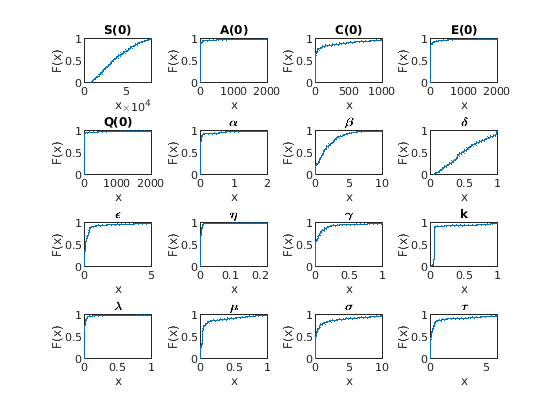

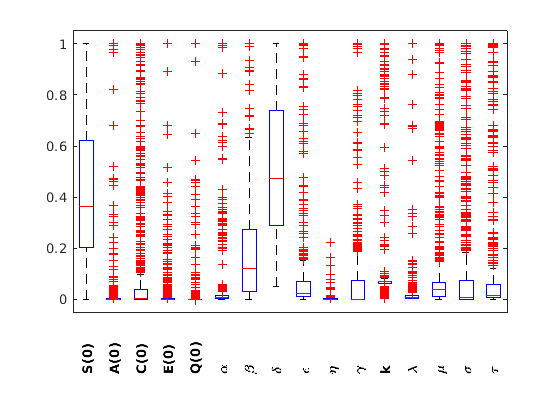

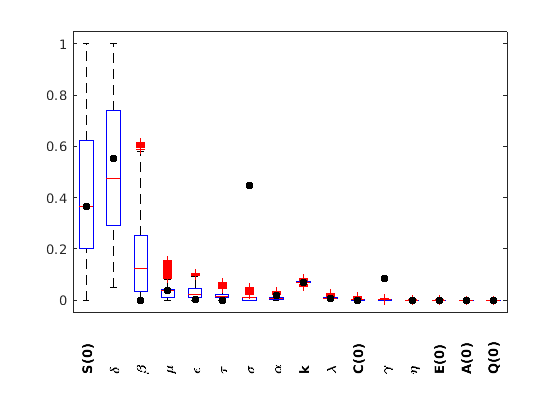

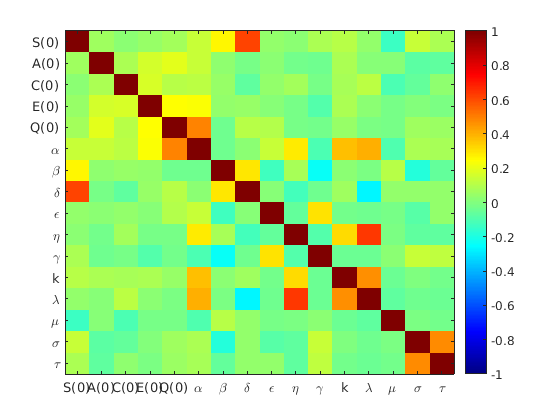

T = 16×4 table
                        Range              Nominal           Est           index  
                ______________________    __________    ______________    ________

    S(0)            32330        35641         33986    [1×800 double]    0.098111
    A(0)                0       16.675       0.26112    [1×800 double]    0.050916
    C(0)                0       23.163        2.4166    [1×800 double]    0.060048
    E(0)                0        15.58        0.3877    [1×800 double]    0.053691
    Q(0)                0       13.088      0.024037    [1×800 double]    0.059265
    \alpha              0     0.036914      0.015844    [1×800 double]    0.082993
    \beta          1.0686       1.3801        1.2243    [1×800 do

T_ia = gsua_ia(T, EstimatedParams(1:N2,:)', false, false);

**Sensitivity analysis (SA): estimation intervals**

Perform the SA using the estimation intervals, i.e., the estimation box

N = 10000; 
M = gsua_dmatrix(T,N,'Method','Sobol');

Unrecognized function or variable 'T'.

T_sa = gsua_sa(M, T);
sum(T_sa.Si)/sum(abs(T_sa.Si))
clf
gsua_plot('Pie',T_sa,T_sa.STi)

**Uncertainty analysis for parametric CI **

Progress: 100%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 15:59:40
Number of simulations: 1000


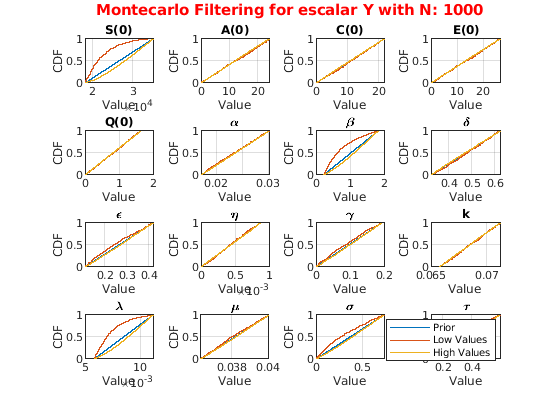

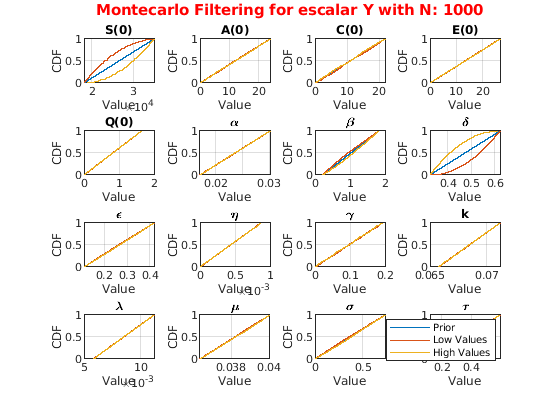

Estimations = readmatrix("../FunctionalIntervals/COVIDIntervals.csv");
Estimations = Estimations(2:end,:);

T.Nominal = Estimations(:,1);
T.Range = Estimations(:,2:3);

clf
N = 1000; 
M = gsua_dmatrix(T,N,'Method','Sobol');
gsua_ua(M, T,'xdata', xdata, 'ynom', ydata(:,outs)', 'parallel', false);

**SA: bootstrap intervals**

Perform the SA using the confident intervals using the median value of the parameters

Estimations = readmatrix("../FunctionalIntervals/COVIDIntervals.csv");
Estimations = Estimations(2:end,:);

T.Nominal = Estimations(:,1);
T.Range = Estimations(:,2:3);

N = 10000; 
M = gsua_dmatrix(T,N,'Method','Sobol');
T_sa = gsua_sa(M, T);

Current outputs:1  3
Progress: 6%
Estimated processing time (h:m:s): 0:1:51
Remaining time (h:m:s): 0:1:44
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 16:2:9
Number of simulations: 90000
Progress: 12%
Estimated processing time (h:m:s): 0:1:42
Remaining time (h:m:s): 0:1:31
Elapsed time (h:m:s): 0:0:11
Estimated stop time (h:m:s): 16:2:1
Number of simulations: 90000
Finding the deepest curve...
Progress: 17%
Estimated processing time (h:m:s): 0:3:39
Remaining time (h:m:s): 0:3:2
Elapsed time (h:m:s): 0:0:36
Estimated stop time (h:m:s): 16:3:58
Number of simulations: 90000
Progress: 23%
Estimated processing time (h:m:s): 0:3:7
Remaining time (h:m:s): 0:2:26
Elapsed time (h:m:s): 0:0:41
Estimated stop time (h:m:s): 16:3:26
Number of simulations: 90000
Progress: 28%
Estimated processing time (h:m:s): 0:2:48
Remaining time (h:m:s): 0:2:1
Elapsed time (h:m:s): 0:0:46
Estimated stop time (h:m:s): 16:3:7
Number of simulations: 90000
Progress: 34%
Estimated processing time (h:m:s):

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 0.9192

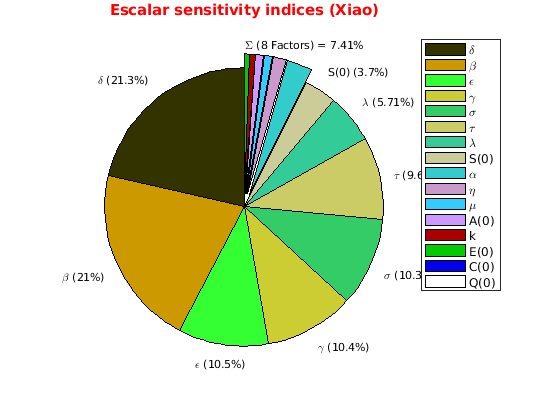

clf
gsua_plot('Pie',T_sa,T_sa.STi)